# Mutagenicity classification using graph convolutional neural networks 

### Introduction

The [Ames test](https://www.sciencedirect.com/topics/pharmacology-toxicology-and-pharmaceutical-science/ames-test) is a bacterial short-term test for identification of carcinogens using [mutagenicity](https://www.sciencedirect.com/topics/pharmacology-toxicology-and-pharmaceutical-science/mutagenicity) in bacteria as an end point. A high, but not complete, correlation has been found between carcinogenicity in animals and mutagenicity in the Ames test. The [Ames dataset](https://weilab.math.msu.edu/DataLibrary/2D/) used in this example, includes 6512 compounds and corresponding binary labels from Ames Mutagenicity results. The goal is to use graph convolutional network (GCN) to predict mutagenicity of given [SMILES](https://en.wikipedia.org/wiki/Simplified_molecular-input_line-entry_system) data as a binary classificatin task.

### Setting up the conda environment and MATLAB workspace

This example uses some of the fucntions from [RDKit](https://www.rdkit.org/). We, therefore set the conda environment using these two lines. Make sure you give your python addess in the first line of "Setup_Conda_Environment.m" pyExec = '...\anaconda3\';

% Setup_Conda_Environment;
% !conda activate DeepChem-env

As a general task, let's first clear up the workspace.

clear;
clc;
close all;

### Read csv data into MATLAB and convert to molecular graphs

We can import data from .csv file as a matrix into MATLAB and visualize. Determine if you want to work form a csv file or the graph matrix is available. For this example, the data is already processed and stored in the "AMES_Data" folder.

%filename = ['AMES_Data_5','.csv']
%[SMILES_Data,Class] = ImportTox21(filename);
%Graph_from_SMILES_Dataset(SMILES_Data,Class);

%return;

### Load data files

The following function uses RDKit to construct the molecular graph for the given SMILES structure. See the examples on [this page](https://www.rdkit.org/docs/GettingStartedInPython.html) to get started with the RDKit in Python. The adjacency and node matrices are stored in "graph_data.mat". 

GraphDataFolder = 'AMES_Data';
[Adjacency,Features,Labels] = Concatenate_Data(GraphDataFolder);

size(Adjacency) is [214   214  6512]
size(Features) is [214     7  6512]
size(Labels) is [1  6512]
Total number of positive molecules is [3503]
Total number of negative molecules is [3009]


### Prepare Data for Training

Partition the data into training, validation, and test partitions. We also do some pre-processing and normalization on the data before training. The details are explained at [MATLAB-GCN](https://www.mathworks.com/help/deeplearning/ug/node-classification-using-graph-convolutional-network.html). 

TrainPart = 0.7;
ValidPart = 0.1;
TestPart = 0.2;
Partitions= [TrainPart,ValidPart,TestPart];
[Adjacency,Features,Labels,classes,numOutputFeatures,numAtoms] = Partition_and_Prepare(Adjacency,Features,Labels,Partitions);


### Training

Choose if you want to retain the network or use the pretrained parameters.

doTraining = true;

Specify training options and parameters:

numHiddenFeatureMaps = 64;
numEpochs = 500; 
learnRate = 0.01;
validationFrequency = 100; 
plots = "training-progress";
executionEnvironment = "cpu";
Params=[numHiddenFeatureMaps,numEpochs,learnRate,validationFrequency];
options = [plots,executionEnvironment];

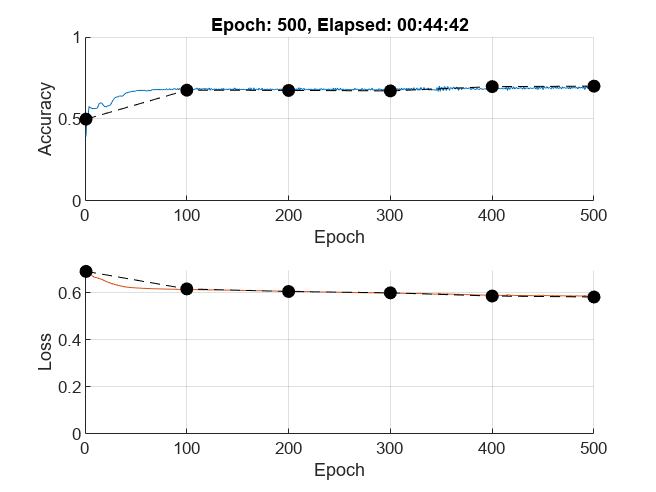

if doTraining == true
  [parameters] = Train_GCN(Adjacency, Features, Labels,Params,options,numOutputFeatures,classes,numAtoms);
else
  load trained_parameters.mat
end


save('parameters_final.mat','parameters')


### Testing

Test the model using the test data. Preprocess the test data using the same steps as for the training and validation data.

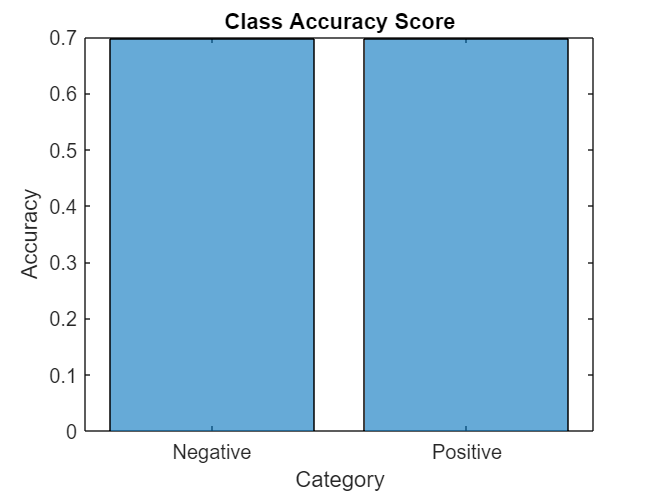

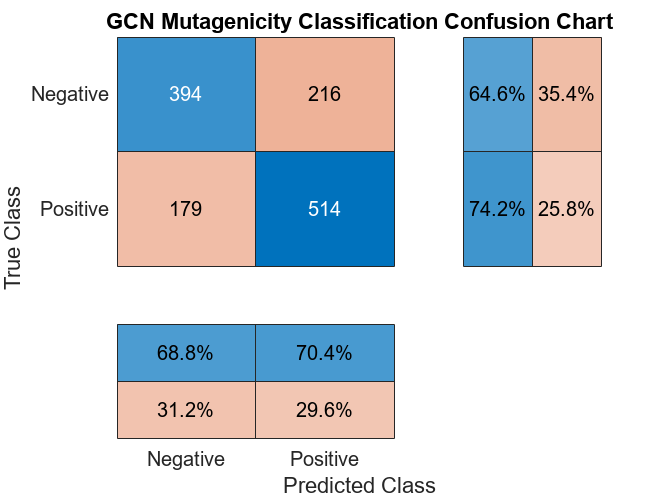

Test_GCN(Adjacency, Features, Labels,Params,options,numOutputFeatures,classes,numAtoms,parameters);